Evaluating...


Plotting graphs...


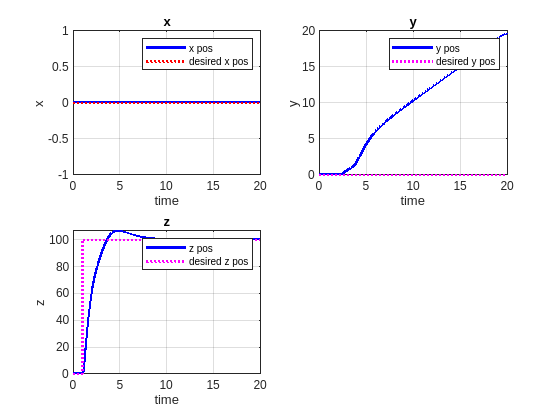

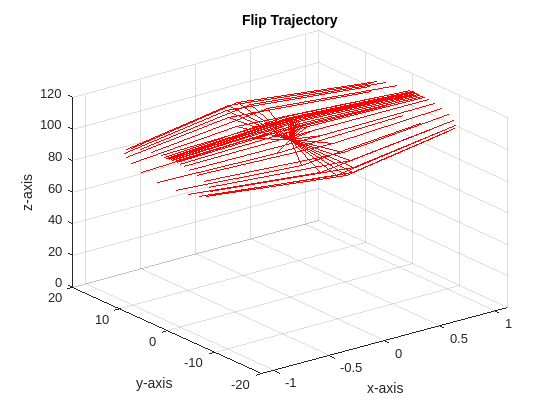

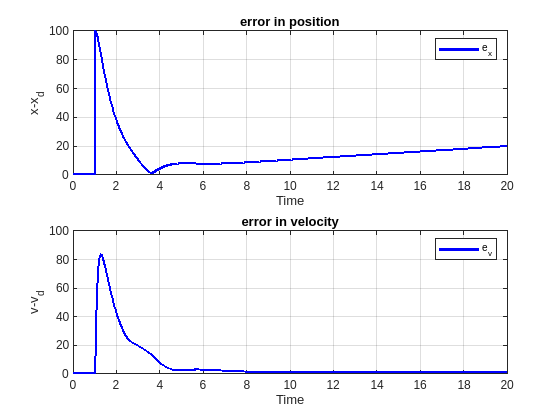

close all; 

clear;

%% System Parameters
quad_params.params.mass = 0.5;  % mass in kg
quad_params.params.J = diag([0.557, 0.557, 1.05] * 10e-2);  % Moment of inertia (kg.m^2)
quad_params.params.g = 9.81;  % gravitational constant (m/s^2)
quad_params.params.e1 = [1; 0; 0];  % Inertial frame axis e1
quad_params.params.e2 = [0; 1; 0];  % Inertial frame axis e2
quad_params.params.e3 = [0; 0; 1];  % Inertial frame axis e3
quad_params.params.d = 0.315;  % Distance of center of mass from frame center (m)
quad_params.params.c = 8.004 * 10e-4;  % Fixed constant (m)
quad_params.params.x_desired = nan;
quad_params.params.gen_traj = 1;  % Change here to generate trajectory
quad_params.params.vel = nan;
quad_params.params.acc = nan;
quad_params.params.b1d = nan;
quad_params.params.w_desired = [0; 0; 0];
quad_params.params.k1 = diag([30, 30, 5]);
quad_params.params.k2 = diag([30, 30, 5]);
quad_params.params.kR = 5;
quad_params.params.kOm = 5;

% Define initial conditions
x_quad_0 = [0; 0; 0];  % Initial position
v_quad_0 = zeros(3,1);  % Initial velocity
R0 = eye(3);  % Initial orientation (identity matrix)
w0 = zeros(3,1);  % Initial angular velocity

% Concatenate initial conditions into a single vector
x0 = [x_quad_0; v_quad_0; reshape(R0, 9, 1); w0];

%% ODE Solver Options
odeopts = odeset('RelTol', 1e-8, 'AbsTol', 1e-9);
[t, x] = ode15s(@odefun_quadDynamics, [0 20], x0, odeopts, quad_params);

%% Compute Various Quantities
disp('Evaluating...');
index = round(linspace(1, length(t), round(1 * length(t))));

for i = index
    [~, xd_, f_, M_] = odefun_quadDynamics(t(i), x(i,:)', quad_params);
    xd(i, :) = xd_';

    R_di = reshape(xd(i, 7:15), 3, 3);
    R_i = reshape(x(i, 7:15), 3, 3);

    h_i(i,1:3) = (R_i*x(i,1:3)')';
    h_di(i,1:3) = (R_di*xd(i,1:3)')';

    pos_err_fx(i) = norm(x(i, 1:3) - xd(i, 1:3));
    vel_err_fx(i) = norm(x(i, 4:6) - xd(i, 4:6));

    % orient_err_fx(i) = norm(R_i*x(i,1:3)' - R_di*xd(i,1:3)');
    
    f(i, 1) = f_;
    M(i, :) = M_';
end

%% Plotting Graphs
plott(t, x, xd, pos_err_fx, vel_err_fx, h_i, h_di);

%% ODE Function for Quadrotor Dynamics

function [dx, xd, f, M] = odefun_quadDynamics(t, x, quad_params)
    % Extract parameters
    mass = quad_params.params.mass;
    J = quad_params.params.J;
    g = quad_params.params.g;
    e1 = quad_params.params.e1;
    e2 = quad_params.params.e2;
    e3 = quad_params.params.e3;

    % Fetch desired states
    traj_desired = return_traj(t);
    x_des = traj_desired.pos;
    v_des = traj_desired.vel;
    a_des = traj_desired.acc;
    % b1d = traj_desired.b1d;
    w_desired = quad_params.params.w_desired;
    w_desired_dot = zeros(3, 1);

    % Current state
    x_curr = x(1:3);
    v_curr = x(4:6);
    R = reshape(x(7:15), 3, 3);
    w = x(16:18);
    b3 = R(:, 3);
    dx = [];

    %% Position Control
    err_x = x_curr - x_des;
    err_v = v_curr - v_des;
    k1 = quad_params.params.k1;
    k2 = quad_params.params.k2;
    A = (-k1 * err_x - k2 * err_v + mass * a_des + mass * g * e3);
    normA = norm(A);
    b3_desired = A / normA;

    f = vec_dot(A, b3);

    
    Rd = traj_desired.orient;

    % Angular velocity and rotation matrix constants
    kR = quad_params.params.kR;
    kOm = quad_params.params.kOm;

    % Calculate error in angular velocity and attitude
    err_R = 1 / 2 * vee_map(Rd' * R - R' * Rd);
    err_Om = w - R' * Rd * w_desired;

    M = -kR * err_R - kOm * err_Om + vec_cross(w, J * w) ...
        - J * (hat_map(w) * R' * Rd * w_desired - R' * Rd * w_desired_dot);

    %% Equations of Motion
    xQ_dot = v_curr;
    vQ_dot = -g * e3 + (f / mass) * R * e3;
    R_dot = R * hat_map(w);
    Omega_dot = J \ (-vec_cross(w, J * w) + M);

    %% Desired state
    xd = [x_des; v_des; reshape(Rd, 9, 1); w_desired];

    %% Return the derivative of state
    dx = [xQ_dot; vQ_dot; reshape(R_dot, 9, 1); Omega_dot];
end


function [traj] = return_traj(times)
    % Generate comprehensive trajectory for a flip maneuver
    % Inputs:
    %   times: Time vector (1xN)
    % Outputs:
    %   pos:    Position trajectory (3xN)
    %   vel:    Velocity trajectory (3xN)
    %   acc:    Acceleration trajectory (3xN)
    %   Rd:     Rotation matrix trajectory (3x3xN)
    
    % Trajectory Parameters
    total_flip_time = 8;   % Total time for flip (seconds)
    flip_start_time = 5;   % Time when the flip starts (seconds)
    flip_end_time = flip_start_time + total_flip_time;
    
    % Preallocate output matrices
    N = length(times);
    traj.pos = zeros(3, N);     % Position
    traj.vel = zeros(3, N);     % traj.velocity
    traj.acc = zeros(3, N);     % traj.acceleration
    Rd = zeros(3, N);   % Rotation matrices
    
    % Initial conditions
    initial_height = 1;    % Starting height
    hover_height = 1;      % Hover height during maneuver
    
    % Compute trajectory for each time point
    for i = 1:N
        t = times(i);
        
        % Position Trajectory
        if t > 1
            traj.pos(3, i) = 100;
        end
       
    end

    total_flip_time = 2;   % Total time for flip (seconds)
    flip_start_time = 2;   % Time when the flip starts (seconds)
    flip_end_time = flip_start_time + total_flip_time; % Time when flip ends
    max_height = 2;        % Maximum height (not used here, but you can expand it)

    % Initialize trajectory
    reference_trajectory = zeros(3, length(times)); % [phi; theta; psi]

    % Generate trajectory
    for i = 1:length(times)
        t = times(i);

        if t < flip_start_time
            % Takeoff phase: Stable orientation
            phi(i) = 0;
            theta(i) = 0;
            psi(i) = 0;
        elseif t <= flip_end_time
            % Flip phase: Perform a 360-degree roll (phi)
            flip_progress = 2 * pi * (t - flip_start_time) / total_flip_time; % Progress from 0 to 2*pi
            phi(i) = flip_progress; % Roll progresses through the flip
            theta(i) = 0; % No pitch
            psi(i) = 0; % No yaw
        elseif t > flip_end_time
            % Stabilization phase: Maintain upright orientation
            phi(i) = 2 * pi;
            theta(i) = 0;
            psi(i) = 0;
        else
            % Stabilization phase: Maintain upright orientation
            phi(i) = 0;
            theta(i) = 0;
            psi(i) = 0;
        end
    end
    traj.orient = RPYtoRot_ZXY(phi, theta, psi);
    
end






%% Plotting Function
function plott(t, x, xd, pos_err_fx, vel_err_fx, h_i, h_di)
    disp('Plotting graphs...');
    index = round(linspace(1, length(t), round(1 * length(t))));

    figure;
    subplot(2, 2, 1);
    plot(t(index), x(index, 1), '-b', 'LineWidth', 2); hold on;
    plot(t(index), xd(index, 1), ':r', 'LineWidth', 2); hold off;
    grid on; title('x'); legend('x pos', 'desired x pos'); xlabel('time'); ylabel('x');

    subplot(2, 2, 2);
    plot(t(index), x(index, 2), '-b', 'LineWidth', 2); hold on;
    plot(t(index), xd(index, 2), ':m', 'LineWidth', 2); hold off;
    grid on; title('y'); legend('y pos', 'desired y pos'); xlabel('time'); ylabel('y');

    subplot(2, 2, 3);
    plot(t(index), x(index, 3), '-b', 'LineWidth', 2); hold on;
    plot(t(index), xd(index, 3), ':m', 'LineWidth', 2); hold off;
    grid on; title('z'); legend('z pos', 'desired z pos'); xlabel('time'); ylabel('z');

    figure
    
    quiver3(xd(1:10:end, 1), xd(1:10:end, 2), xd(1:10:end, 3), h_di(1:10:end,1), h_di(1:10:end,2), h_di(1:10:end,3), 1.3, 'r');hold on;  % b1 (Red)
    
    % quiver3(pos(:,1), pos(:,2), pos(:,3), R(:,2,1), R(:,2,2), R(:,2,3), 0.1, 'g', 'LineWidth', 1.5);  % b2 (Green)


    hold off;
    grid on;
    title('Flip Trajectory');
    % legend('b1 (Red)');
    xlabel('x-axis'); ylabel('y-axis'); zlabel('z-axis');


    % Plot position and velocity errors
    figure;
    subplot(2,1,1);
    plot(t(index),pos_err_fx(index),'-b','LineWidth',2);
    grid on; title('error in position');
    legend('{e}_x');
    xlabel('Time');ylabel('{x}-{x}_d');
    subplot(2,1,2);
    plot(t(index),vel_err_fx(index),'-b','LineWidth',2);
    grid on; title('error in velocity');legend('{e}_v');
    xlabel('Time');ylabel('{v}-{v}_d');

end





